# Figure 5G, 5H, 5I

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F033_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
frameDrugAdded = 16;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .01;
        end


    end
    S(i).apcExpressGate = apcExpressGate;

  S(i).POI(:, 1) = S(i).traceStats(:,1);
    S(i).POI(:,6) = S(i).traceStats(:,2);
    S(i).POI(~S(i).isMother,6) = NaN;

end

Find threshold, Cyclin A OE

conds=[1 2];
cols =  [0 0 1;.8 .2 1; 1 .5 .2; 1 .5 .2;  .855 .384 .49];
linetype = {'-','-','--','--'};
timeGate = [2 drug_time];

figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
           inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 104

ans = 121

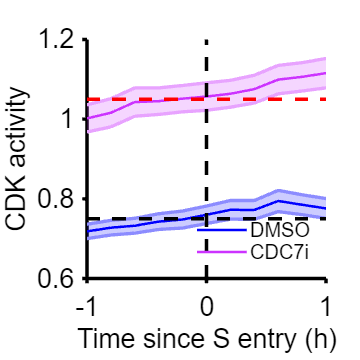


ylabel({'CDK activity'});xlabel('Time since S entry (h)');
legend('DMSO','CDC7i','box','off','Location','southeast','fontsize',12);

xlim([-1 1]); 
ylim([.6 1.2]);
vline([0],'k--')
hline(1.05,'r--')
hline(.75,'k--')

5G

conds=[2 7];

colors =  [ .6 .9 .2;  .8 0 .5];
linetype = {'-','-','--','--'};
timeGate = [0 10];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
           inds = ~isnan(S(conds(i)).POI(:,POI_align))  &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 653

ans = 638

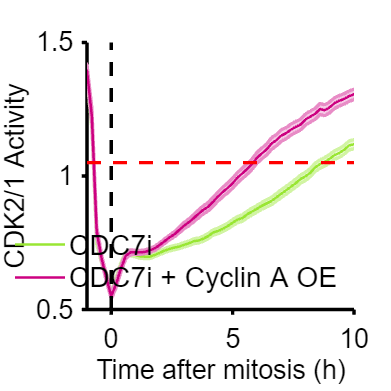


ylabel({'CDK2/1 Activity'});xlabel('Time after mitosis (h)');
legend('CDC7i','CDC7i + Cyclin A OE','box','off','Location','southeast','fontsize',17);

xlim([-1 10]); 
xticks(0:5:20)
ylim([.5 1.5]);
vline([0],'k--')
hline(1.05,'r--')


 % print_pdf(['fig_5G.pdf'])


5H

conds=[3 7];
 colors = [.6 .9 .2;  .8 0 .5;.1 .4 1; .6 .9 .2];

 clear cols
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 10];

for i=1:length(conds)
    c = conds(i);
    data = S(c);

 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 200000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 186

ans = 521

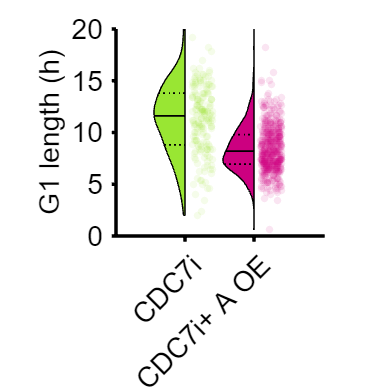


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'CDC7i','CDC7i+ A OE'})
ylim([0 20])
yticks(0:5:25)
 xtickangle(45)
axis square
set(gca,'fontsize',17,'linewidth',2)



 p=mediantest(ally(groups==1),ally(groups==2))

p = 4.9692e-18


   % print_pdf(['fig_5h.pdf'])


Find threshold Cyclin E OE 

conds=[11 12];


colors = [0 0 1;.8 .2 1;0 0 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','--','--','--'};
timeGate = [2 drug_time];

figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
           inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 102

ans = 115

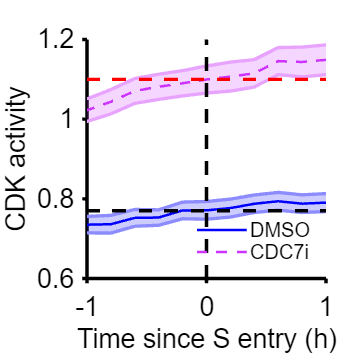


ylabel({'CDK activity'});xlabel('Time since S entry (h)');
legend('DMSO','CDC7i','box','off','Location','southeast','fontsize',12);

xlim([-1 1]); 
ylim([.6 1.2]);
vline([0],'k--')
hline(1.1,'r--')
hline(.77,'k--')

5I left

conds=[14 19];


colors =  [ 0 .5 1;1 .5 .2;1 .5 .2; 1 .5 .2;  .855 .384 .49];
linetype = {'-','-','--','--'};
timeGate = [2 drug_time];

figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
           inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 146

ans = 153

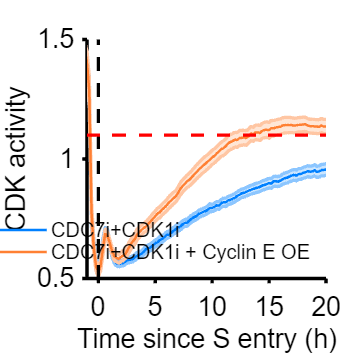


ylabel({'CDK activity'});xlabel('Time since S entry (h)');
legend('CDC7i+CDK1i','CDC7i+CDK1i + Cyclin E OE','box','off','Location','southeast','fontsize',12);

xlim([-1 20]); 
xticks(0:5:20)
ylim([.5 1.5]);
vline([0],'k--')
hline(1.1,'r--')


 % print_pdf(['fig_5I_left.svg'])


5I right

conds=[14 19];
colors = [0 .5 1;1 .5 .2;.8 .2 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
timeGate = [2 drug_time];
cols =  [ 1 .5 .2; 1 .5 .2;  .855 .384 .49];
linetype = {'-','-','--','--'};

figure('unit','inches','position',[0 0 4 6])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk& (S(conds(i)).POI_realtime(:,3) > drug_time | isnan(S(conds(i)).POI(:,3)) );

     event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    
   plot(x,f, 'Color',colors(i,:),'linestyle',linetype(i),'LineWidth',1.5);
 
    sum(inds)
end

ans = 146

ans = 153

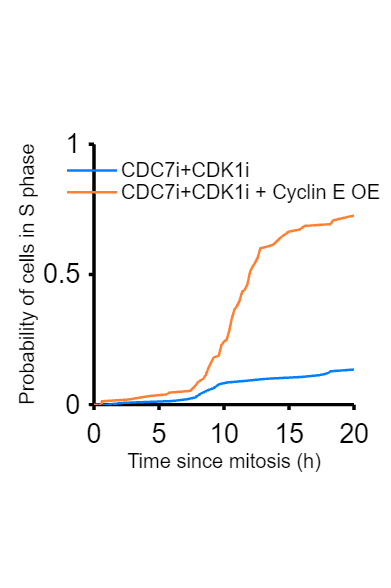



axis square
legend('CDC7i+CDK1i','CDC7i+CDK1i + Cyclin E OE','Box','off','Location','north','FontSize',12);
xlim([0 20]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time since mitosis (h)','FontSize',12)
ylabel('Probability of cells in S phase','FontSize',12)
hold on

 % print_pdf(['fig_5i_right.svg'])